# Fault Identification in Simulink 

This example demonstrates how to estimate unknown inputs and states of a discrete-time, linear time-invariant (LTI) plant using the ULISE filter [1] in Simulink®. You will use the [ULISE Filter](matlab:open('../../html/ULISE_Filter_Block_overview.html')) and [LTI Plant](matlab:open('../../html/LTI_Plant_Block_overview.html')) blocks to estimate the faults (unknown inputs or disturbances) and states [2].

### Introduction:

In this example, we estimate the faults and states of a discrete-time LTI system. 

The estimator handles both observable and unobservable fault components, estimating the known input with a **one-step delay** $d_{k-1} \in \mathbb{R}^3$, while the state vector $x_k \in \mathbb{R}^5$ is estimated with **zero-step delay** [1].

The Simulink model shown below implements this workflow.

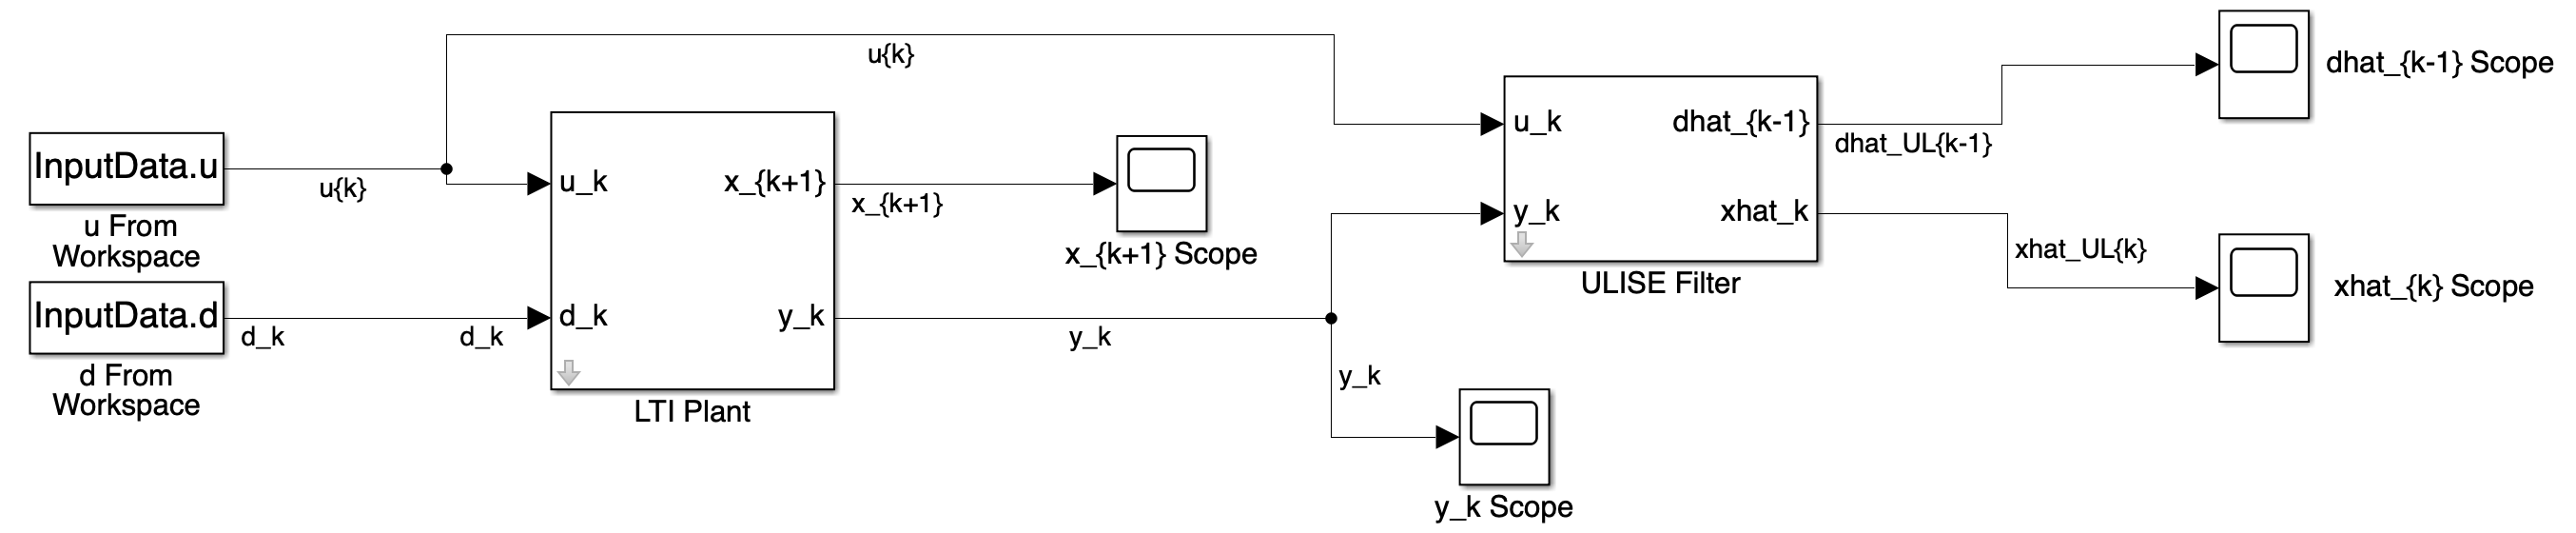

Figure 1: Simulink model of a discrete-time LTI plant using the ULISE Filter to estimate states and unknown inputs. 

In general, the Simulink workflow will consists of two main components: 

- Defining system and simulation parameters inside the **initialization callback script.** 

- Using the **LTI Plant** and **ULISE Filter** blocks to set up and simulate the model workspace. 

### Initialization Callback Script:

To run this example, all system parameters and simulations settings are definedin the initialization script [`InitFcn_ULISE.m`](matlab:open('./ulise_callbacks/InitFcn_ULISE.m'))`. `

This script is automatically executed when the example model is run, ensuring consistent/updated parameterization.

For a general LTI system with $$n$$ states $x_k \in \mathbb{R}^n
$, $$m$$ known inputs $u_k \in \mathbb{R}^m
$, $$p$$ unknown inputs $d_{k-1} \in \mathbb{R}^p
$, and $$l$$ measured outputs  $y_k \in \mathbb{R}^l 
$, the file **must** define the following structures:

**Simulation Setup struct (**`SimSetup`**):**

- Simulation sample time $Ts$ (default 1 second for discrete-time systems)

- Total time steps $K $

- Total simulation time $T$

- Time vector $t$ for generating timeseries objects

**System struct, **`System`**:**

- State transition matrix$A$($n$-by-$n$)

- Control input matrix $B
$ ($n$-by-$m$)

- Measurement matrix $$C$$($l$-by-$n$)

- Direct feedthrough from $u_k$ matrix $D$ ($l$-by-$m$)

- Disturbance input matrix $G$ ($n$-by-$p$)

- Disturbance feedthrough to output matrix $H
$ ($n$-by-$p$)

- Process noise covariance $Q$ ($n$-by-$n$) and its Cholesky decomposition denoted `CholQ`

- Measurement noise covariance $R$ ($l$-by-$l$) and its Cholesky decomposition denoted `CholR`

- Initial condition of the state, $x_0$ denoted `x0`

- Initial states estimate, $\hat{x}_{0|0}$ denoted `xhat0`

- Initial state error covariance, $P^x_{0|0}$ ($n$-by-$n$) denoted `P_x0`

Learn more ahout MATLAB's Cholesky decomposition function, [`chol`](https://www.mathworks.com/help/matlab/ref/chol.html)`.`

**Input Data Struct, **`InputData`**:**

- Timeseries object of the known input `u` matrix ($m$-by-$K$) where each column is $u_k$at time step $k$

- Timseries object of the unknown input `d` matrix ($p$-by-$K$) where each column is $d_k$ at time step $k$

Learn more about MATLAB's [`timeseries`](https://www.mathworks.com/help/matlab/ref/timeseries.html) function. 

**Example excerpt (defining the unknown input **`d):`

The following excerpt of code from `InitFcn_ULISE.m` illustrates how to do this for the unknown input `d` ($d_k \in \mathbb{R}^3$).

% Initialize the input data struct
InputData = struct();

%% Simulate 'true' known input, u, and unknown input, d. 
d = zeros(p,SimSetup.K); 
d(1,500:700) = 1*ones(size(d(1,500:700)));

for j = 100:800
    d(2,j) = 1/700*(j-100);
end

% Modify the third disturbance component
d(3,[500:549 600:649 700:749]) = 3*ones(size(d(3,[500:549 600:649 700:749])));
d(3,[550:599 650:699 750:799]) = -3*ones(size(d(3,[550:599 650:699 750:799])));

% Add unknown input timeseries to struct
InputData.d=setinterpmethod(timeseries(d, SimSetup.t),'zoh');
InputData.d.Name = "timeseries unknown input";

Once all the parameters are defined, open the Simulink model:

open_system("SISE/Examples/Simulink/ulise_internal_v0.slx");

Unable to find system or file 'SISE/Examples/Simulink/ulise_internal_v0.slx'.

### LTI Plant and ULISE Filter Design:

ULISE is an algorithm to estimate zero-step state $\hat{x}_k = \left[ \matrix{ \hat{x}^{(1)}_{k} & \hat{x}^{(2)}_{k}   & \hat{x}^{(3)}_{k}  & \hat{x}^{(4)}_{k}  & \hat{x}^{(5)}_{k} } \right]^T$ and one-step unknown input delay $\hat{d}_{k-1} = \left[ \matrix{ \hat{d}^{(1)}_{k-1} & \hat{d}^{(2)}_{k-1}   & \hat{d}^{(3)}_{k-1}  } \right]^T$ based on a discete-time linear time invariant model.

The model describes how the system's state and unkown input evolve over time due to the initial conditions $x_0$, known inputs $u_k$, and measured output $y_k$. In this example we estimate $x_k$ and $d_{k-1}$ where $k$ is the discrete-time index.

The LTI system is modeled as:

$x_{k+1} = A x_k + B u_k + G d_k + w_k$,


$$y_k = C x_k + D u_k + H d_k + v_k$$


where $x_k 
$ is the state vector, $u_k 
$ is the known input, $d_k 
$ is the unknown inputs, $y_k 
$ is the measured outputs, $w_k 
$ is the process noise, and $v_k 
$ is the measurement noise. The process noise and measurement noise are zero-mean vectors and uncorrelated i.e., $\mathbb{E}[w_k v_k^T] = 0$ with error covariances $\mathbb{E}[w_k w_k^T]  = Q$ and $\mathbb{E}[v_k v_k^T] = R$, repsectively. 

The following system and noise matrices $A$,$B$,$C$,$D$,$G$, $H$, $Q$, and $R$ have the values:

$A = \left[ \matrix{0.5 & 2 & 0 & 0 & 0 \cr 0 & 0.2 & 1 & 0 & 1 \cr 0 & 0 & 0.3 & 0 & 1 \cr 0 & 0 & 0 & 0.7 & 1 \cr 0 & 0 & 0 & 0 & 0.1} \right]$; 

$B = \left[ \matrix{0 \cr 0 \cr 0  \cr 0 \cr 0 } \right]$; 

$C = \left[ \matrix{1 & 0 & 0 & 0 & 0 \cr 0 & 1 & 0 & 0 & 0 \cr 0 & 0 & 1 & 0 & 0 \cr 0 & 0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 0 & 1} \right]$; 

$D = \left[ \matrix{0 \cr 0 \cr 0  \cr 0 \cr 0 } \right]$; 

$G = \left[ \matrix{ 1 & 0 & -0.3 \cr 1 & 0 & 0 \cr 0 & 0 & 0  \cr  0 & 0 & 0  \cr 0 & 0 & 0} \right]$; 

$H = \left[ \matrix{ 0 & 0 & 1 \cr 0 & 0 & 0 \cr 0 & 1 & 0  \cr  0 & 0 & 0  \cr 0 & 0 & 0} \right]$;

$Q = 10^{-4} \ \left[ \matrix{1 & 0 & 0 & 0 & 0 \cr 0 & 1 & 0.5 & 0 & 0 \cr 0 & 0.5 & 1 & 0 & 0 \cr 0 & 0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 0 & 1} \right]$;

$R = 10^{-2}\ \left[ \matrix{1 & 0 & 0 & 0.5 & 0 \cr 0 & 1 & 0 & 0 & 0.3 \cr 0 & 0 & 1 & 0 & 0 \cr 0.5 & 0 & 0 & 1 & 0 \cr 0 & 0.3 & 0 & 0 & 1} \right]$.

The $A$ matrix describes the system dynamics between consecutive time steps, while the C (a $5$-by-$5$ identity matrix) indicates that all states are observable.

For modeling purposes, we assume that we don't have known input being added to our system i.e., $u_k = 0 \in \mathbb{R}^1
$, and so the $B$ and $D$ matrices are both ($5$-by-$1$) zero vectors. 

The unkown input is $d_k = \left[ \matrix{d_1 & d_2 & d_3} \right]^T$, has observable and unobservable components because $H$ is rank-deficient.

- The unobservable components, $d_{2, k-1} = \left[ \matrix{ d_1} \right]$, is estimated from the **state equation** at time step k-2 .

- The observable components, $d_{1, k} = \left[ \matrix{d_2 & d_3} \right]^T$, are estimated directly from the **measurement equation** at time step k. 

Lastly, $Q$ must be positive semi-definite and $R
$ must be a postive definite matrix to ensure valid (stochastic) modeling.

### LTI Plant and ULISE Filter Block Inputs and Setup:

**LTI Plant**

Click on the LTI Plant block and under the section **System Model** Please specify the following systems matrices: 

- **A**: The A matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`. `

- `B:` The B matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`. `

- `C``:` The C matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`.`

- `D:` `T`he D matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`.  `

- `G:` The G matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`. `

- `H:` The H matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`.`

- **Initial State x[0]**: `0`. This represents an initial guess of $x_k$ 0 at t=0s.

- **Sample time (-1 for inherited)**: Ts, which is defined earlier in this example to be 1 second..

Please see the image below. 

<LTI Plant Block Image>

LTI Plant Block Mask

**ULISE Filter block**

Click on the ULISE FIlter block and under the section **System Model** Please specify the following system and noise covariance matrices: 

- **A**: The A matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`. `

- `B:` The B matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`. `

- `C``:` The C matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`.`

- `D:` `T`he D matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`.  `

- `G:` The G matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`. `

- `H:` The H matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`.`

- `Cholesky Q:` The cholesky decomposed of the  process matrix Q defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`. `

- `Cholesky R:` The R matrix is defined earlier in this example. We inherit the value from the `InitFcn_ULISE.m` by typing the correspoinding variable name used in the script`.   `

- **Initial State Estimate  xhat[0]**: `0`. This represents an initial guess of $\hat{x}_k$ 0 at t=0s.

- **Initial State Error Covariance Px[0]**: `10`. Assume that the error between your initial guess x[0] and its actual value is a random variable with a standard deviation 

- **Sample time (-1 for inherited)**: Ts, which is defined earlier in this example.

Please see the image below. 

<ULISE Filter Block Image>

ULISE Filter Block Mask

### Results:

sim("SISE/Examples/Simulink/example_ULISE_fault_identification.mlx")

Below provides example code to generate visualizations of your system and filter dynamics. Figure 1 plots ULISE state and disturbance estimates against true values over time, and Figure 2 plots the traces of their error covariance matrices over time.

set(0,'defaulttextinterpreter','latex')
num=25; k=1:K;

% Figure 1
fig1 = figure;
sgtitle('Figure 1')

subplot(4,2,1)
plot(k,x(1,:),'k-',k,xhat_UL(1,:),'b--','LineWidth',1);
hold on
plot(k(1:num:end),xhat_UL(1,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$x_1$')
h=legend(h1,'$x_1$','$\hat{x}^{\rm ULISE}_1$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')


subplot(4,2,2)
plot(k,x(2,:),'k-',k,xhat_UL(2,:),'b--','LineWidth',1);
hold on
plot(k(1:num:end),xhat_UL(2,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$x_2$')
h=legend(h1,'$x_2$','$\hat{x}^{\rm ULISE}_2$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,3)
plot(k,x(3,:),'k-',k,xhat_UL(3,:),'b--','LineWidth',1);
hold on
plot(k(1:num:end),xhat_UL(3,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$x_3$')
h=legend(h1,'$x_3$','$\hat{x}^{\rm ULISE}_3$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,4)
plot(k,x(4,:),'k-',k,xhat_UL(4,:),'b--','LineWidth',1);
hold on
plot(k(1:num:end),xhat_UL(4,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$x_4$')
h=legend(h1,'$x_4$','$\hat{x}^{\rm ULISE}_4$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,5)
plot(k,x(5,:),'k-',k,xhat_UL(5,:),'b--','LineWidth',1);
hold on
plot(k(1:num:end),xhat_UL(5,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$x_5$')
h=legend(h1,'$x_5$','$\hat{x}^{\rm ULISE}_5$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,6)
plot(k,d(1,:),'k-',k,dhat_UL(1,:),'r--','LineWidth',1);
hold on
plot(k(1:num:end),dhat_UL(1,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$d_1$')
h=legend(h1,'$d_1$','$\hat{d}^{\rm ULISE}_1$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,7)
plot(k,d(2,:),'k-',k,dhat_UL(2,:),'r--','LineWidth',1);
hold on
plot(k(1:num:end),dhat_UL(2,1:num:end),'bv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$d_2$')
h=legend(h1,'$d_2$','$\hat{d}^{\rm ULISE}_2$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

subplot(4,2,8)
plot(k,d(3,:),'k-',k,dhat_UL(3,:),'r--','LineWidth',1);
hold on
plot(k(1:num:end),dhat_UL(3,1:num:end),'rv');
grid on
h1=plot(0,0,'k-',0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('$d_3$')
h=legend(h1,'$d_3$','$\hat{d}^{\rm ULISE}_3$');
set(h,'Interpreter','latex','Orientation','horizontal','Location','Best')

% Extract the trace of the state and unknown input error covariance matrices, respectively.
trX_UL=zeros(k(end),1);
trD_UL=zeros(k(end),1);
for i=k
   trX_UL(i)=trace(Px_UL(:,:,i));
   trD_UL(i)=trace(Pd_UL(:,:,i)); 
end

% Figure 2
fig2 = figure;
sgtitle('Figure 2')

subplot(1,2,1)
semilogy(k,trX_UL,'b--');
hold on
semilogy(k(1:num:end),trX_UL(1:num:end),'bv');
grid on
h1=plot(0,0,'bv--','LineWidth',1);
xlabel('Time, k')
ylabel('trace($P^x$)')
h=legend(h1,'ULISE');
set(h,'Interpreter','latex','Location','Best')

subplot(1,2,2)
semilogy(k,trD_UL,'r--');
hold on
semilogy(k(1:num:end),trD_UL(1:num:end),'bv');
grid on
h1=plot(0,0,'rv--','LineWidth',1);
xlabel('Time, k')
ylabel('trace($P^d$)')
h=legend(h1,'ULISE');
set(h,'Interpreter','latex','Location','Best')

### Summary:

This example demonstrated **fault identification** in a discrete-time, linear time-invariant system. 

The ULISE Filter blcok accurately estimated the system's states and one-step delayed unknown inputs, and performance was validated through compairson with the true values and their covariance traces. 

bdclose("SISE/Examples/Simulink/ulise_internal_v0.slx");

### References:

[1] Yong, S. Z., Zhu, M., & Frazzoli, E. (2016). *A unified filter for simultaneous input and state estimation of linear discrete-time stochastic systems.* *Automatica, 63,* 321–329. [https://doi.org/10.1016/j.automatica.2015.10.040](https://doi.org/10.1016/j.automatica.2015.10.040) 

*(Also available as a preprint at *[*https://arxiv.org/abs/1309.6627*](https://arxiv.org/abs/1309.6627?utm_source=chatgpt.com)*)*

[2] Keller, J. Y., Summerer, L., Boutayeb, M., & Darouach, M. (1996). Generalized likelihood ratio approach for fault detection in linear dynamic stochastic systems with unknown inputs. International journal of systems science, 27(12), 1231-1241.

D. Lawson, S. Macero, E. Gah, and S.Z. Yong (2025). SISE Toolbox for MATLAB (https://github.com/dalawson0/SISE/), GitHub.